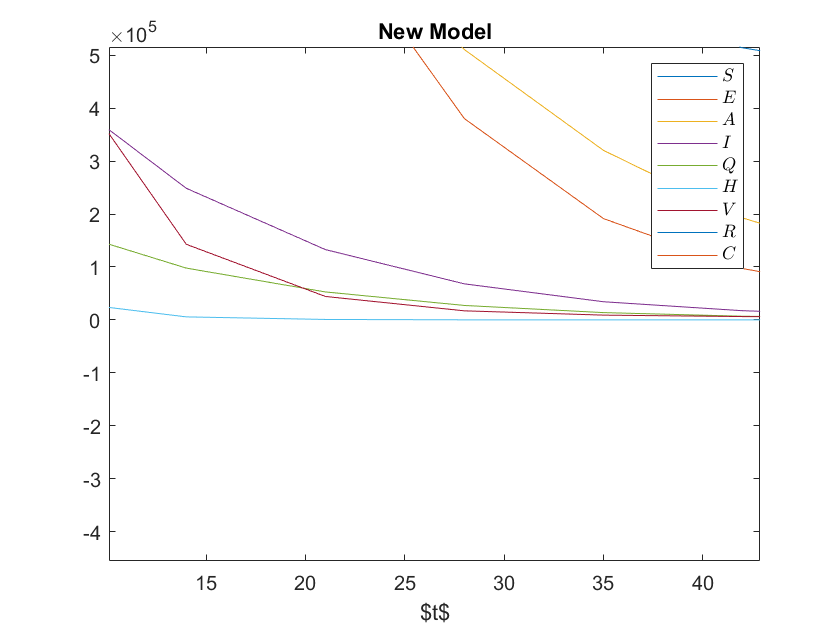

clear all;
load data\cases.csv
load data\deaths.csv
cases = [0; cases(1:end-1)];
cases = cases(2:end)-cases(1:end-1);
cases = cases/10500000;
params.N = 10000000;
params.beta = 0.5;
params.c = 1.33;
params.theta = 0.002;
params.alpha = 0.167;
params.epsilon = 0.3;
params.gamma1 = 0.1;
params.mu = 0.4;
params.kappa = 0.25;
params.gamma2 = 0.1;
params.gamma3 = 0.1;
params.rho = 0.22;
params.gamma4 = 0.09;
params.gamma5 = 0.2;
y0 = [450; 50; 50; 50; 100; 25; 200; 75; 0];
obj = @(x) objective(x, cases);

%params = fminsearch(obj,rand(2,1));
%p.beta = params(1);
%p.c = 1.33
% p.theta = params(3);
% p.alpha = params(4);
% p.epsilon = params(5);
% p.gamma1 = params(6);
% p.mu = params(7);
% p.theta = 0.002;
% p.alpha = 0.167;
% p.epsilon = 0.3;
% p.gamma1 = 0.1;
% p.mu = 0.4;
%p.kappa = params(2);
% p.gamma2 = params(9);
% p.gamma3 = params(10);
% p.rho = params(11);
% p.gamma4 = params(12);
% p.gamma5 = params(13); 
% p.gamma2 = 0.1;
% p.gamma3 = 0.1;
% p.rho = 0.22;
% p.gamma4 = 0.09;
%p.gamma5 = 1.2;
ode = @(t, y) rhs(y, params);

I0 = .5;
y0 = [.45; I0; .050; .050; .100; .025; .200; .075; 0]*10000000;

tspan = 0:7:490;

[t,y] = ode45(ode, tspan, y0);
sir_cases = y(:,9);
sir_cases = sir_cases(2:end)-sir_cases(1:end-1);
% ode = @(t, y) rhs(y, params);
%@ is anon function.returns sir rhs (defined at the bottom) 

% %initial conditions for S I and R
% tspan = 0:497;
% %solving from t=0 to t=10
% [t,y] = ode45(ode, tspan, y0);
% 
% sir_cases = y(:,9);
% sir_cases = [0; sir_cases(1:end)];
% sir_cases = sir_cases(2:end)-sir_cases(1:end-1);
figure()
plot(t,y)
legend(["$S$", "$E$", "$A$", "$I$", "$Q$", "$H$", "$V$", "$R$" , "$C$"], "Interpreter","latex")
title("New Model")
xlabel("$t$")

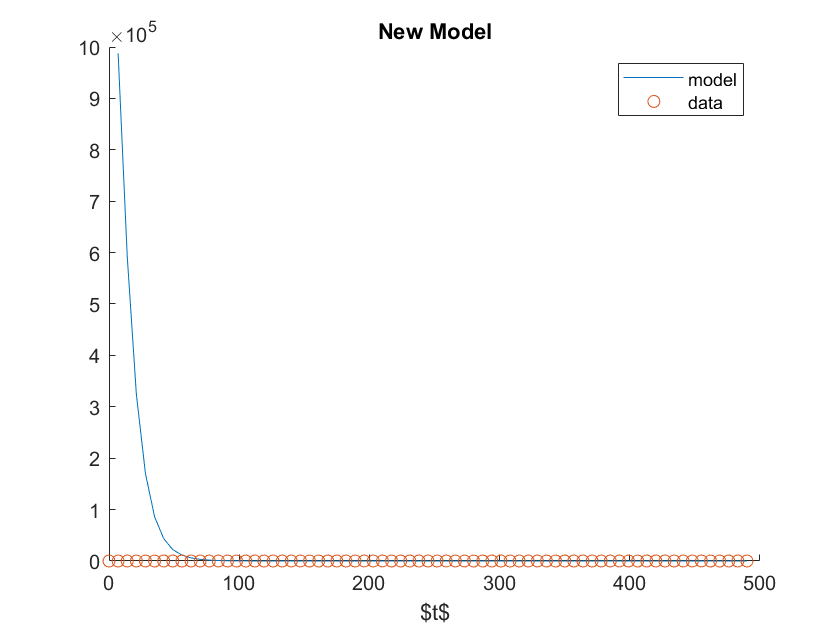

figure()
hold on
plot(t(2:end), sir_cases);
%
scatter(0:7:490, cases)
hold off
%legend(["$S$", "$E$", "$A$", "$I$", "$Q$", "$H$", "$V$", "$R$"], "Interpreter", "latex")
legend(["model", "data"])
title("New Model")
xlabel("$t$")

function dxdt = rhs(x, params)
    beta = params.beta;
    c = params.c;
    theta = params.theta;
    alpha = params.alpha;
    epsilon = params.epsilon;
    gamma1 = params.gamma1;
    mu = params.mu;
    kappa = params.kappa;
    gamma2 = params.gamma2;
    gamma3 = params.gamma3;
    rho = params.rho;
    gamma4 = params.gamma4;
    gamma5 = params.gamma5;
    lambda = beta*(x(3)+c*x(4))/(x(1)+x(2)+x(3)+x(4)+x(7)+x(8));
    dxdt(1) = -(lambda + theta)*x(1);
    dxdt(2) = lambda*x(1) - alpha*x(2);
    dxdt(3) = alpha*epsilon*x(2) - gamma1*x(3);
    dxdt(4) = alpha*(1-epsilon)*x(2) - (mu + kappa +gamma2)*x(4);
    dxdt(5) = kappa*x(4) - (gamma3 + rho +mu)*x(5);
    dxdt(6) = rho*x(6) - (mu +gamma4)*x(6);
    dxdt(7) = theta*x(1) - gamma5*x(7);
    dxdt(8) = gamma1*x(3) + gamma2*x(4) + gamma3*x(5) + gamma4*x(6) + gamma5*x(7);
    dxdt(9) = kappa*x(4);
    dxdt = dxdt';
end
function res = objective(params, data)
    p.beta = params(1);
    p.c = params(2);
    p.theta = params(3);
    p.alpha = params(4);
    p.epsilon = params(5);
    p.gamma1 = params(6);
    p.mu = params(7);
    p.kappa = params(8);
    p.gamma2 = params(9);
    p.gamma3 = params(10);
    p.rho = params(11);
    p.gamma4 = params(12);
    p.gamma5 = params(13); 
    ode = @(t, y) rhs(y, p);
    I0 = .2;
    y0 = [.45; I0; .050; .050; .100; .025; .200; .075; p.kappa*I0]*10000000;

    tspan = 0:490;
    
    [t,y] = ode45(ode, tspan, y0);
    sir_cases = y(:,9);
    sir_cases = [0; sir_cases(1:end)];
    sir_cases = sir_cases(2:end)-sir_cases(1:end-1);
    res = data - sir_cases(1:7:end);
    res = res'*res;
    
end